# Slenderness study on transverse shear-locking

In this section it is investigated the behavior of the convergence as the slenderness (length over thickness) goes to infinity $L/t \rightarrow \infty$, namely, as the thickness goes to zero $t \rightarrow 0$. As the thickness goes to zero, the spurious forces due to transverse shear locking increase, leading to an ever increasing artificially stiffening behavior. To keep the solution constant the same scaling factor is applied both to the applied force and the thickness, so that the ratio $p/t$, and thus the resulting deformation, remains constant.

Go to [THIS](matlab:open('./main_Chapter4_Locking_ReissnerMindlinSquarePlate.mlx')) Section in the main driver script *Transverse Shear Locking in Shear-Deformable Plates *`-`* Cantilever Plate Subject to Vertical Distributed Load*

Go to [PREVIOUS](matlab:open('./main_Chapter41_ReissnerMindlinSquarePlate_ShearForces.mlx')) Section *Transverse-shear locking due incompatible discretization spaces*

Go to [NEXT](matlab:open('./main_Chapter43_ReissnerMindlinSquarePlate_ConvergenceStudy.mlx')) Section *Convergence study on transverse shear-locking*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

vars = ["propStr" "XLx" "mshQ1" "mshQ2" "numNodesElQ1" ...
    "numNodesElQ2" "numDOFsQ1" "numDOFsQ2" "freeDOFsQ1" "freeDOFsQ2"];
str = "This mlx-file should be run from parent " + ...
    "main_Chapter3_Locking_ReissnerMindlin_SquarePlate.mlx";
for ii = 1:length(vars)
    if ~exist(vars(ii), 'var') 
        error(strcat("Variable ", vars(ii), " is not defined. ", str));
    end
end

## Initialize array of the resulting vertical deflection with respect to the slenderness

propStrSlend = propStr;
numPtsSlend = mPowU - mPowL + 1;
slendernessRatio = 10.^linspace(mPowL, mPowU, numPtsSlend);
numSlendLevels = numel(slendernessRatio);
tipDeflectionSlend = zeros(numSlendLevels, 3);

## Define reference solution for this problem by means of the Kirchhoff plate theory

tipDeflectionKirchhoffSlend = ...
    repmat(0.487463124419606, numSlendLevels, 1);

## Point for the displacement evaluation

xyPostProc = [XLx 0];

## Element in mesh containing the evaluation point

elPstProc = nan;
for ii = 1:numEl
    [in, ~] = inpolygon(xyPostProc(1), xyPostProc(2), ...
        mshQ1.nodes(mshQ1.elements(ii, :), 1), ...
        mshQ1.nodes(mshQ1.elements(ii, :), 2));
    if in
        elPstProc = ii;
        break;
    end
end
if isnan(elPstProc)
    error("No element found containing the point where the " + ...
        "postprocessing results are evaluated");
end
propNewtonRaphson.eps = 1e-12;
propNewtonRaphson.maxIt = 20;
[xiEta, isConverged] = ...
    computePointCoordinatesOnCanonicalBilinearQuadrilateral ...
    (xyPostProc', mshQ1.nodes(mshQ1.elements(elPstProc, :), 1:2)', ...
    propNewtonRaphson);
if ~isConverged
    error("The parametric coordinates of point (%d, %d) can not be " + ...
        "found in element %d", xyPostProc(1), xyPostProc(2), elPstProc);
end

## Element Freedom Tables (EFTs) for the bilinear and the biquadratic quadrilateral meshes at the element containing the evaluation point

EFTQ1PostprocSlend = [3*mshQ1.elements(elPstProc, :) - 2
                      3*mshQ1.elements(elPstProc, :) - 1
                      3*mshQ1.elements(elPstProc, :)];
EFTQ1PostprocSlend = EFTQ1PostprocSlend(:);
EFTQ2PostprocSlend = [3*mshQ2.elements(elPstProc, :) - 2
                      3*mshQ2.elements(elPstProc, :) - 1
                      3*mshQ2.elements(elPstProc, :)];
EFTQ2PostprocSlend = EFTQ2PostprocSlend(:);

## Basis functions and set-up the basis function matrices at the parametric location of the evaluation point

### Basis functions matrix for the bilinear quadrilateral mesh

ShapeFunctionValuesQ1 = ...
    computeBilinearBasisFunctionsAndFirstDerivatives ...
    (xiEta(1, 1), xiEta(2, 1));
NmtxQ1 = zeros(3, 3*numNodesElQ1);
for ii = 1:numel(ShapeFunctionValuesQ1(:, 1))
    NmtxQ1(1, 3*ii - 2) = ShapeFunctionValuesQ1(ii, 1);
    NmtxQ1(2, 3*ii - 1) = ShapeFunctionValuesQ1(ii, 1);
    NmtxQ1(3, 3*ii) = ShapeFunctionValuesQ1(ii, 1);
end

### Basis functions matrix for the biquadratic quadrilateral mesh

ShapeFunctionValuesQ2 = ...
    computeBiquadraticBasisFunctionsAndFirstDerivatives ... 
    (xiEta(1, 1), xiEta(2, 1));
NmtxQ2 = zeros(3, 3*numNodesElQ2);
for ii = 1:numel(ShapeFunctionValuesQ2(:, 1))
    NmtxQ2(1, 3*ii - 2) = ShapeFunctionValuesQ2(ii, 1);
    NmtxQ2(2, 3*ii - 1) = ShapeFunctionValuesQ2(ii, 1);
    NmtxQ2(3, 3*ii) = ShapeFunctionValuesQ2(ii, 1);
end

## Loop over all the slenderness levels

for ii = 1:numSlendLevels

### **Scaling of the externally applied load and the thickness of the plate based on the slederness to obtain dimensionless quantities**

    propStrSlend.t = propStr.t/slendernessRatio(ii);
    propStrSlend.pBar = propStr.pBar/slendernessRatio(ii)^3;
    propStrSlend.D = ...
        propStrSlend.E*propStrSlend.t^3/12/(1 - propStrSlend.nu^2);

### Master stiffness matrix  corresponding to the bilinear quadrilateral mesh

    computeStiffMatrixandForceVectorQ1 = 'undefined';
    computeBasisFunctionsAndDerivsQ1 = ...
        @computeBilinearBasisFunctionsAndFirstDerivatives;
    [KQ1Sled, FQ1Sled] = ...
        computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
        (mshQ1, computeBasisFunctionsAndDerivsQ1, ...
        computeStiffMatrixandForceVectorQ1, propStrSlend);

### Master stiffness matrix  corresponding to the biquadratic quadrilateral mesh

    computeStiffMatrixandForceVectorQ2 = 'undefined';
    computeBasisFunctionsAndDerivsQ2 = ...
        @computeBiquadraticBasisFunctionsAndFirstDerivatives;
    [KQ2Sled, FQ2Sled] = ...
        computeMasterStiffMatrixandForceVctReissnerMindlinPlatePageWise ...
        (mshQ2, computeBasisFunctionsAndDerivsQ2, ...
        computeStiffMatrixandForceVectorQ2, propStrSlend);

### Master stiffness matrix  corresponding to the bilinear quadrilateral mesh using Assumed Natural Strain (ANS)

    computeStiffMatrixandForceVector_Q1_ANS = ...
        @computeElementStiffMatrixandForceVectorReissnerMindlinPlateANS;
    computeBasisFunctionsAndDerivs_Q1_ANS = ...
        @computeBilinearBasisFunctionsAndFirstDerivatives;
    [KQ1ANSSled, FQ1ANSSled] = ...
        computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
        (mshQ1, computeBasisFunctionsAndDerivs_Q1_ANS, ...
        computeStiffMatrixandForceVector_Q1_ANS, propStrSlend);

### Solve the linear equation system corresponding to the bilinear quadrilateral mesh

    uQ1Sled = zeros(numDOFsQ1, 1);
    uQ1Sled(freeDOFsQ1, 1) = ...
        KQ1Sled(freeDOFsQ1, freeDOFsQ1)\FQ1Sled(freeDOFsQ1);

### Solve the linear equation system corresponding to the biquadratic quadrilateral mesh

    uQ2Sled = zeros(numDOFsQ2, 1);
    uQ2Sled(freeDOFsQ2, 1) = ...
        KQ2Sled(freeDOFsQ2, freeDOFsQ2)\FQ2Sled(freeDOFsQ2);

### Solve the linear equation system corresponding to the bilinear quadrilateral mesh using Assumed Natural Strain (ANS)

    uQ1ANSSled = zeros(numDOFsQ1, 1);
    uQ1ANSSled(freeDOFsQ1, 1) = ...
        KQ1ANSSled(freeDOFsQ1, freeDOFsQ1)\FQ1ANSSled(freeDOFsQ1);

### Vertical deflection at the selected point corresponding to the bilinear quadrilateral mesh

    wPostprocQ1 = NmtxQ1*uQ1Sled(EFTQ1PostprocSlend);
    tipDeflectionSlend(ii, 1) = wPostprocQ1(1);

### Vertical deflection at the selected point corresponding to the biquadratic quadrilateral mesh

    wPostprocQ2 = NmtxQ2*uQ2Sled(EFTQ2PostprocSlend);
    tipDeflectionSlend(ii, 2) = wPostprocQ2(1);

### Vertical deflection at the selected point corresponding to the bilinear quadrilateral mesh using Assumed Natural Strain (ANS)

    wPostprocQ1ANS = NmtxQ1*uQ1ANSSled(EFTQ1PostprocSlend);
    tipDeflectionSlend(ii, 3) = wPostprocQ1ANS(1);

end

## Plot the results of the slenderness study

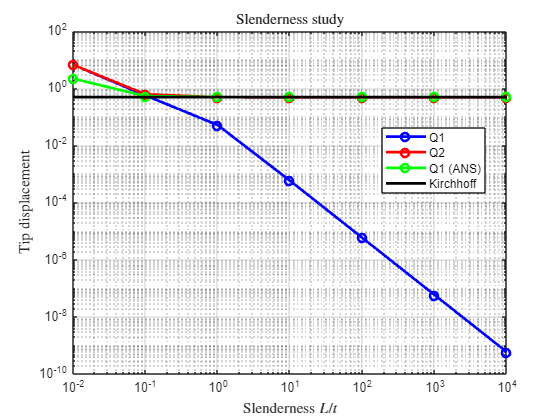

loglog(slendernessRatio, abs(tipDeflectionSlend(:, 1)), "-bo", LineWidth=2)
hold on;
loglog(slendernessRatio, abs(tipDeflectionSlend(:, 2)), "-ro", LineWidth=2)
loglog(slendernessRatio, abs(tipDeflectionSlend(:, 3)), "-go", LineWidth=2)
loglog(slendernessRatio, abs(tipDeflectionKirchhoffSlend), "-k", LineWidth=2)
hold off;
grid on;
legend("Q1", "Q2", "Q1 (ANS)", "Kirchhoff", Location="best")
xlabel("Slenderness $L/t$", "Interpreter", "latex")
ylabel("Tip displacement", "Interpreter", "latex")
title("Slenderness study", "Interpreter", "latex")